10.45

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
s = tf('s');
P = mot.k / (s * (mot.T * s + 1));

dz = 0.9;
w0 = 2 * pi;
C = (s^2 + 2 * dz * w0 * s + w0^2) / (s^2 + w0^2);

Sia L la funzione di trasferimento in catena aperta e T quella in catena chiusa.

L = C * P;
T = minreal(feedback(L, 1), 1e-6);

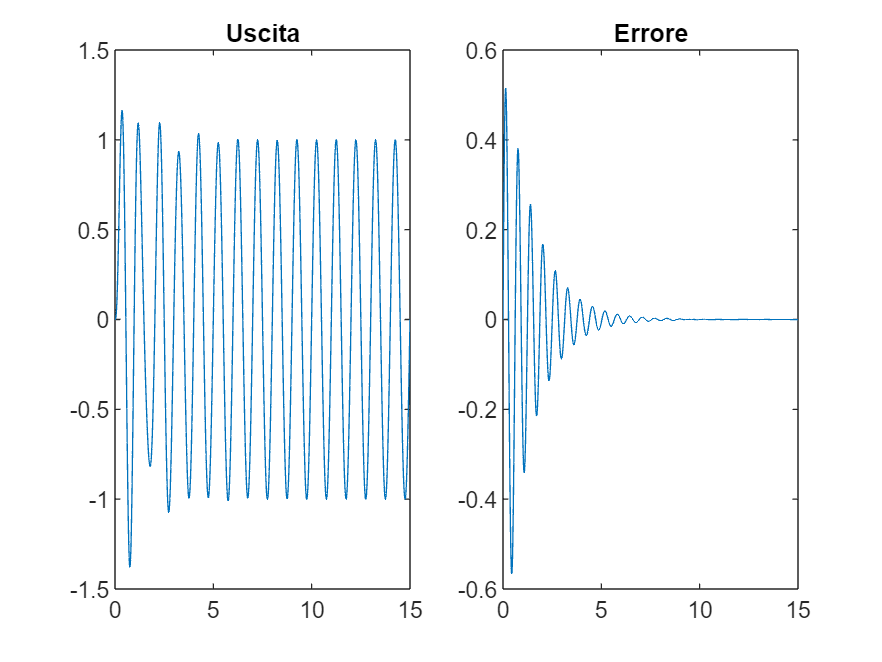

t = 0:0.01:15;
r = sin(w0 * t);

yr = lsim(T, r, t).';
er = r - yr;

close all
figure(1)
subplot(1, 2, 1)
plot(t, yr)
title("Uscita")

subplot(1, 2, 2)
plot(t, er)
title("Errore")

Il controllore contiene i poli immaginari jw0 e -jw0, dunque, per il principio del modello interno, il sistema è in grado di seguire perfettamente un ingresso sinusoidale, cioè l'errore a regime è nullo.

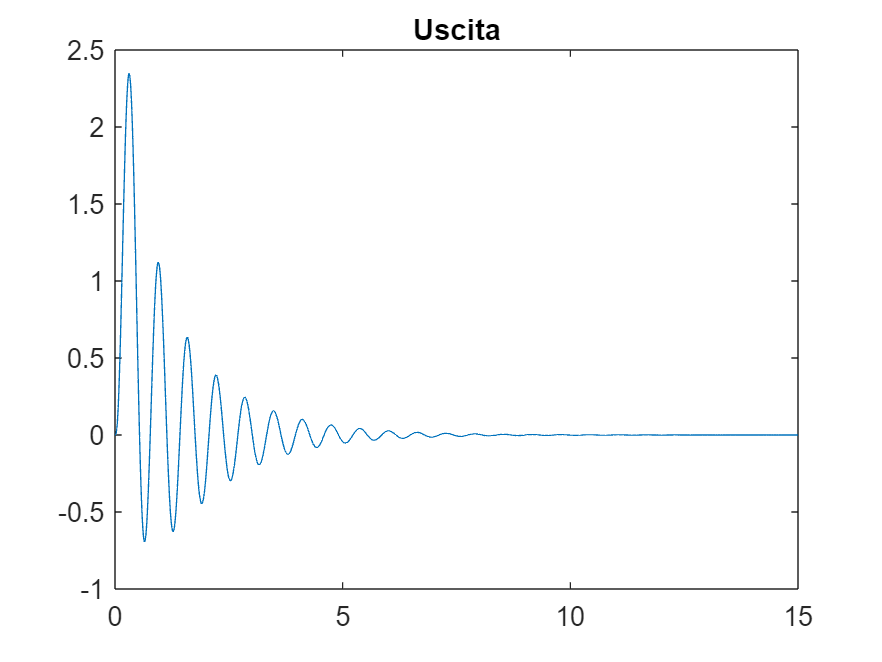

Td = minreal(feedback(P, C), 1e-6);

d = 5 * sin(w0 * t);
yd = lsim(Td, d, t).';

close all
figure(2)
plot(t, yd)
title("Uscita in presenza di disturbo sinusoidale")

Come prima, per il principio del modello interno, è garantita la perfetta reiezione di disturbi sinusoidali.

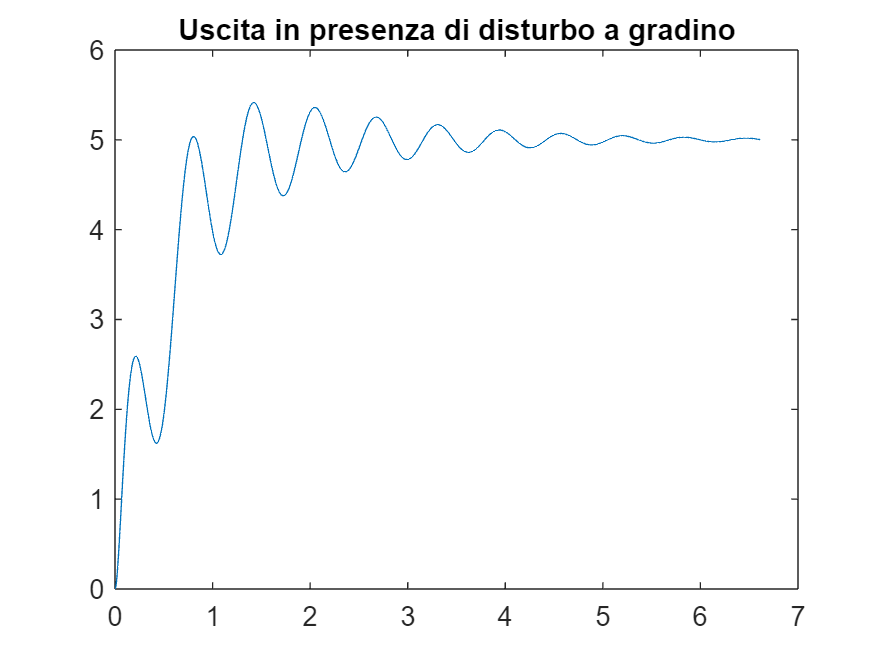

opt = stepDataOptions("StepAmplitude", 5);
[ys, ts] = step(Td, opt);

close all
figure(3)
plot(ts, ys)
title("Uscita in presenza di disturbo a gradino")

Il controllore non presenta poli nell'origine, dunque non permette la reiezione di disturbi a gradino, la cui trasformata di Laplace è 1 / s.